clear all
close all
clc

f = 60 % frequency

f = 60

w = 2*pi*f

w = 376.9911

Tcycle = 1/f

Tcycle = 0.0167

delta_T = 1/f/100;
length_T = 1/f*3;
t = [0:delta_T:length_T]';
Va_rms = 120

Va_rms = 120

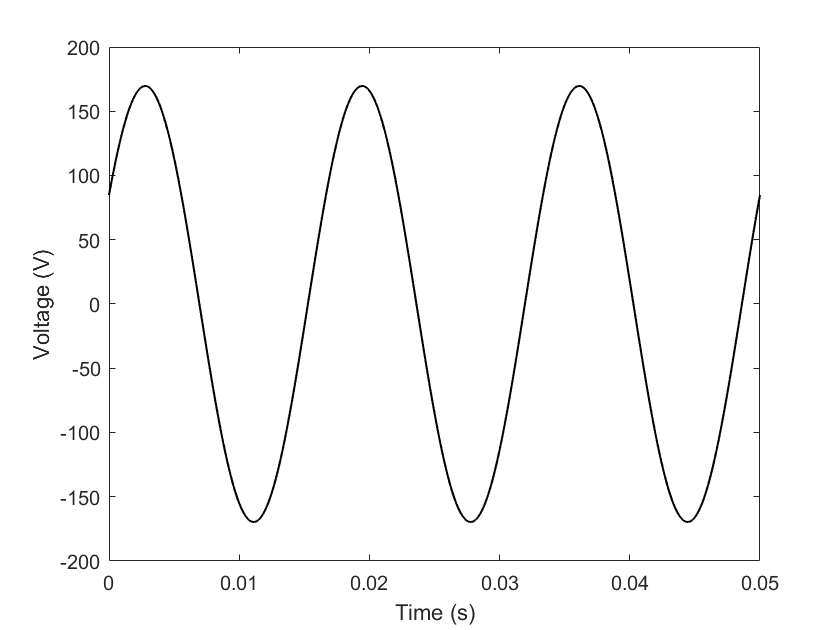

%method 1
Va = Va_rms*sqrt(2)*cos(w*t - 1/3*pi); %angle is in radians. 
%Va = Va_rms*sqrt(2)*cos(w*t - 120/360*2*pi); %angle is in radians. 
figure(1)
plot(t,Va,'k','LineWidth',1)
xlabel('Time (s)')
ylabel('Voltage (V)')
hold on

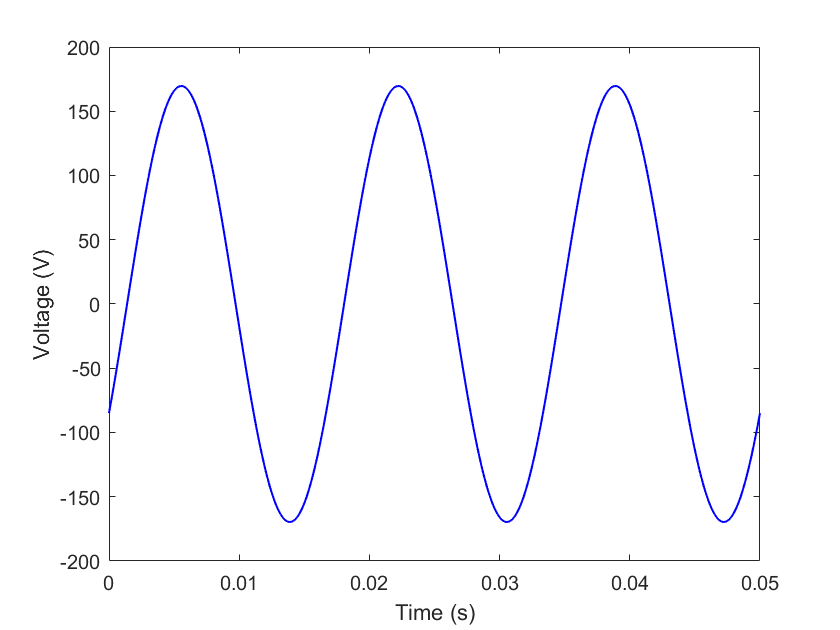

%method 2
Va = Va_rms*sqrt(2)*cosd(rad2deg(w*t) - 120); %angle is in degree.

figure(2)
plot(t,Va,'b','LineWidth',1)
xlabel('Time (s)')
ylabel('Voltage (V)')
hold on

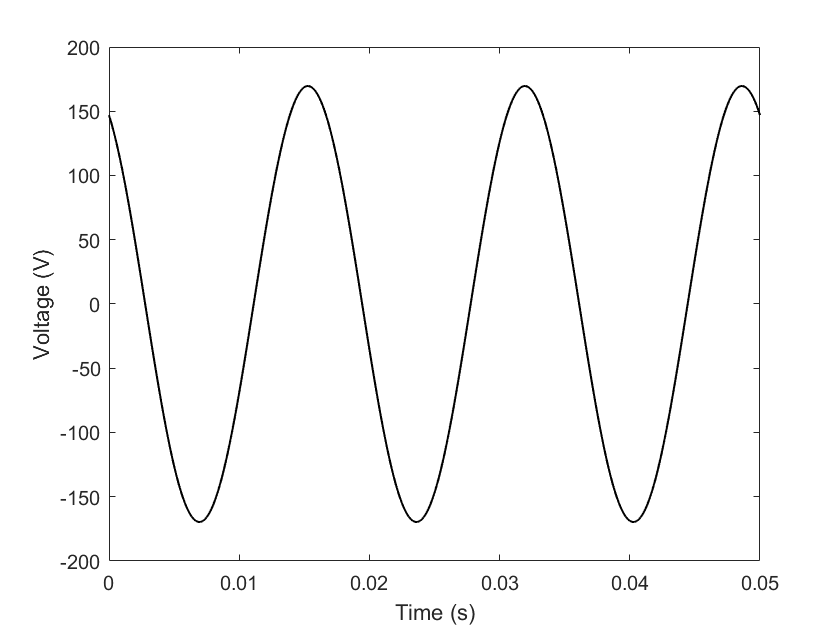

%method 3
% Euler's identity: exp(jX) = cos(x) + j*sin(X)
% cos(X) = the real part of exp(jX)

Va =real(Va_rms*sqrt(2)*exp(1j*(w*t+pi/6)));
figure(3)
plot(t,Va,'k','LineWidth',1)
xlabel('Time (s)')
ylabel('Voltage (V)')
hold on